# Integración Numérica

Existen integrales que pueden ser halladas analíticamente haciendo uso del segundo teorema fundamental del cálculo. Sin embargo, no todas las funciones poseen antiderivada. En general:


$$\int_a^b f\left(x\right)=F\left(b\right)-F\left(a\right),\;\frac{\textrm{d}}{\textrm{d}x}F\left(x\right)=f\left(x\right)$$


En muchas ocasiones resolver una integral de forma analítica puede ser muy tedioso. Por otro lado, también se puede contar con datos obtenidos de forma experimental, por lo que se debe emplear un método numérico para estimar el valor de su integral.

Integrar la función $f\left(x\right)=\ln \left(x\right)$ de $1$ a $2$ usando el método de simpson compuesto 1/3 con $10$ intervalos y compararlo con la solución analítica.

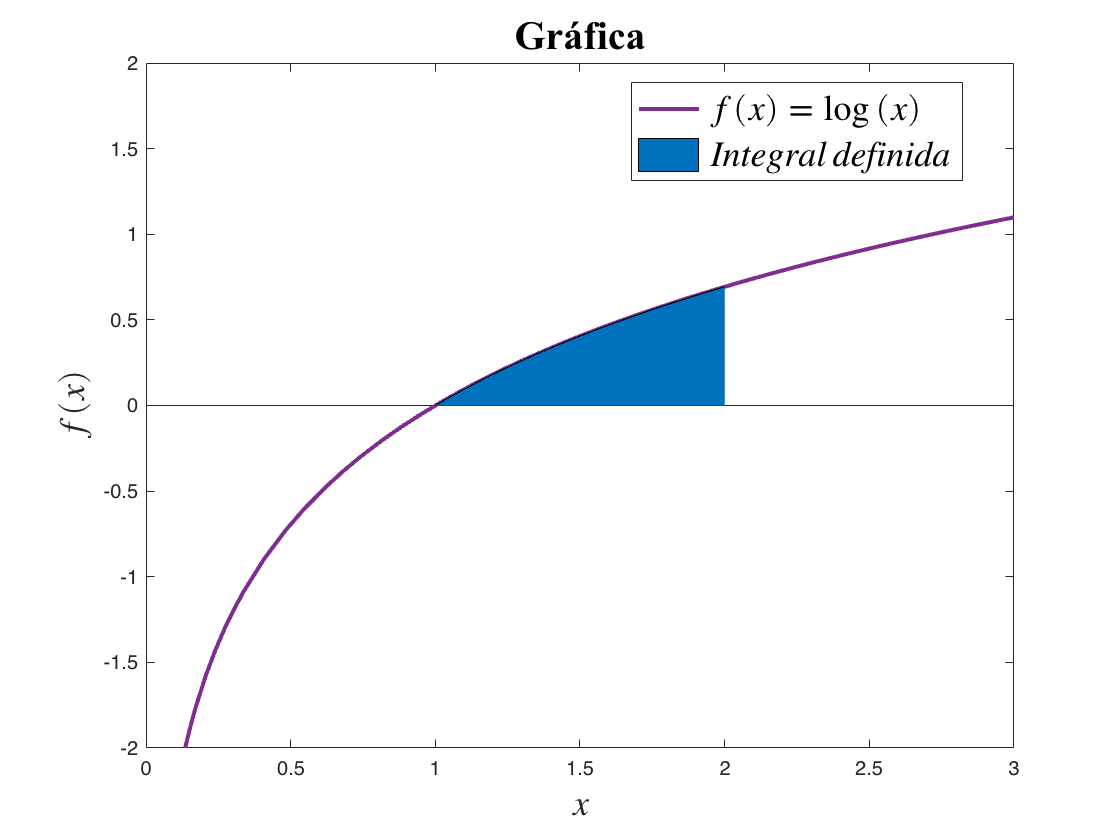

syms x;

f = @(x) (log(x));

a = 1;
b = 2;

fplot(f, Color='#7E2F8E', LineWidth=2)

hold on;

axis([0 3 -2 2]) % xlim([0 3]) ylim([-2 2])
xx = linspace(a, b);
area(xx, f(xx));
colororder('#0072BD')

legend({'$f(x) = \log \left(x\right)$', '$Integral\,definida$'}, 'Interpreter','latex', 'FontSize',18, 'Location','best')
title('Gráfica', 'FontSize',20, 'FontName','Times New Roman')
xlabel('$x$', 'Interpreter','latex', 'FontSize',18)
ylabel('$f(x)$', 'Interpreter','latex', 'FontSize',18)

hold off;

Mediante la función **int** se puede calcular la integral definida exacta de una función $f\left(x\right)$ en el intervalo $\left\lbrack a,b\right\rbrack$.

[I1] = vpa(int(f(x), a, b))

$$I1 = 0.38629436111989061883446424291635$$

La sintaxis de la función **quad**, basada en el método de integración de Simpson, es la siguiente.

[I2] = vpa(quad(f, a, b)) %#ok<DQUAD> 

$$I2 = 0.38629433433641630069033112704346$$

La función **trapz** se puede utilizar para integrar una función $f\left(x\right)$ que no se conoce explícitamente. Es decir, que se da en forma de datos tabulados o puntos $\left(x_i ,y_i \right)$. Este método utiliza integración por el método de trapecio.

[I3] = vpa(trapz(xx, f(xx)))

$$I3 = 0.38629010987831485790522378920286$$